
tau = 0.0505;
k = -1.58

k = -1.5800

sysT = tf(k ,[ tau 1 0])


sysT =
 
      -1.58
  --------------
  0.0505 s^2 + s
 
Continuous-time transfer function.
Model Properties


sysV = tf(k ,[ tau 1 ])


sysV =
 
     -1.58
  ------------
  0.0505 s + 1
 
Continuous-time transfer function.
Model Properties


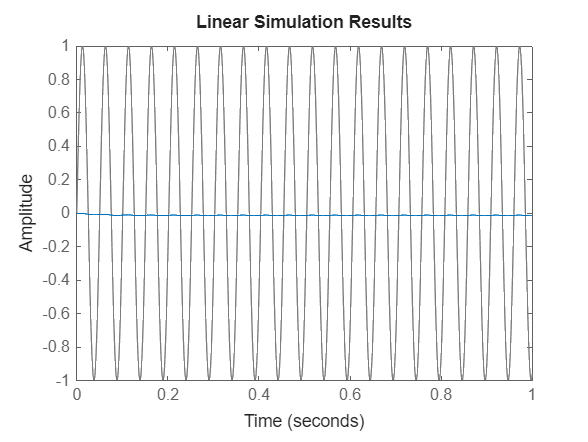



[u,t] = gensig("sine",tau,1);
lsim(sysT,u,t)

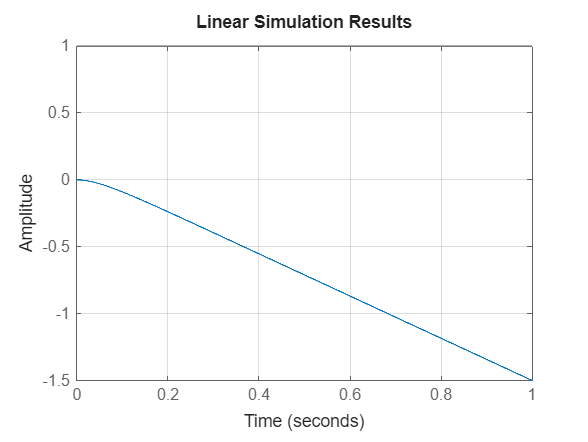


uv= ones(1268,1);
lsim(sysT,uv,t)
grid on

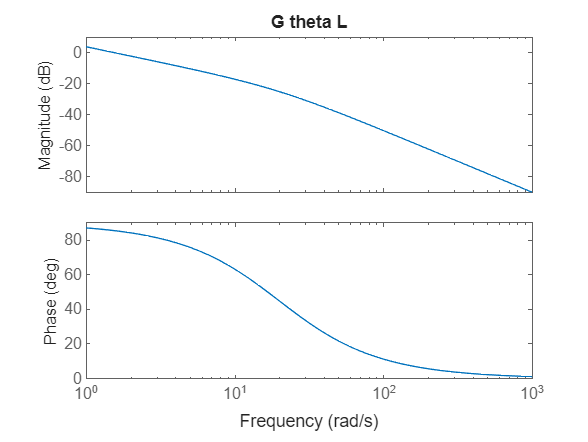


bode(sysT)
title("G theta L")

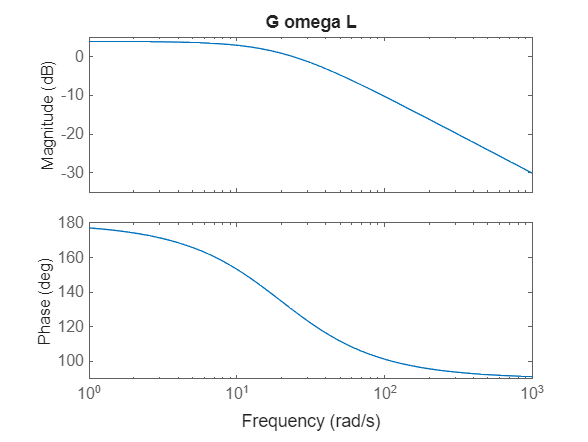

bode(sysV)
title("G omega L")